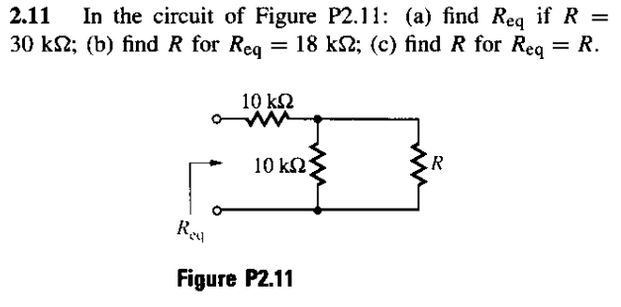

a) Calculamos la resistencia equivalente cuando R = 30k

r1 = 10000;
r2 = r1;
r = 30000;

r_eq = r1 + 1/((1/r2)+(1/r)) %ohms

r_eq =        17500


b) calculamos R si Req es 18k, despejando r de la ecuacion anterior e igualando Req = 18k

syms x
r = solve(r1 + 1/((1/r2)+(1/x))==18000,x) %ohms

$$r = 40000$$

c) Finalmente calculamos R cuando Req = R

req = solve((((r1*x)/(x+r1))+r1) == x,x);
r_vec = double(req)

r_vec =       -6180.3
        16180


Como no tiene sentido resistencias negativas, seleccionamos el valor que tiene sentido

r = r_vec(2,1)

r =         16180


Finalmente tenemos el valor que deberia tiene R para que Req sea igual a R